clearvars
addpath('G:\My Drive\Matlab_work\BC\Sea-Bird_Oxygen_Toolbox')
addpath('G:\My Drive\Matlab_work\BC\Sea-Bird-Toolbox')
addpath('G:\My Drive\Matlab_work\Functions\GSW')
addpath('C:\Users\fogaren\Desktop')
cd('G:\My Drive\Matlab_work\OSU\GeneralCode')
run('GeneralSettings.m')

cd('G:\Shared drives\NSF_Irminger\OOI Cruises CTD Casts\CTD_Data\Alfresco\Year1')

% Casts 
% cast01 = readSBScnv( 'KN22104001_hyst.cnv' );
cast02 = readSBScnv( 'KN22104002_hyst.cnv' );
cast03 = readSBScnv( 'KN22104003_hyst.cnv' );
cast04 = readSBScnv( 'KN22104004_hyst.cnv' );
cast05 = readSBScnv( 'KN22104005_hyst.cnv' );
cast06 = readSBScnv( 'KN22104006_hyst.cnv' );
cast07 = readSBScnv( 'KN22104007_hyst.cnv' );
cast08 = readSBScnv( 'KN22104008_hyst.cnv' );
cast09 = readSBScnv( 'KN22104009_hyst.cnv' );

cd('G:\Shared drives\NSF_Irminger\OOI Cruises CTD Casts\CTD_Data\Alfresco\Year1')
btl = readtable('Irminger_Sea-01_KN221-04_Discrete_Summary_KF.xlsx','TextType','string');
btl.Winkler_mLL = double(btl.Winkler_mLL);
btl.Discrete_Salinity_psu = double(btl.Discrete_Salinity_psu);

btlsum05 = btl(btl.Cast == 5,:);
btlsum06 = btl(btl.Cast == 6,:);
btlsum07 = btl(btl.Cast == 7,:);
btlsum09 = btl(btl.Cast == 9,:);

cd('G:\Shared drives\NSF_Irminger\OOI Cruises CTD Casts\CTD_Data\Alfresco\Bottle_Files\Year1')

btl05 = readtable('KN22104005_hyst.csv','TextType','string');

btl06 = readtable('KN22104006_hyst.csv','TextType','string');

btl07 = readtable('KN22104007_hyst.csv','TextType','string');

btl09 = readtable('KN22104009_hyst.csv','TextType','string');


% Join tables 
btlsum05 = join(btl05,btlsum05,'Keys',"Bottle");
btlsum06 = join(btl06,btlsum06,'Keys',"Bottle");
btlsum07 = join(btl07,btlsum07,'Keys',"Bottle");
btlsum09 = join(btl09,btlsum09,'Keys',"Bottle");

clear btl0* btl1* btl2*

% Oxygen Sensor for cast 2 on; different one cast 1  
% Calibration standards from SBE xmlcon file 

cal.SOC = double(4.55930e-001);
cal.VOFFSET = double(-4.97100e-001);
cal.A = double(-3.66900e-003);
cal.B = double(1.91110e-004);
cal.C = double(-2.62760e-006);
cal.E = double(3.60000e-002);
cal.Tau20 = double(2.23000e+000);
cal.INSTRUMENT_TYPE = 'SBE43';
cal.SERIALNO = '1679';
cal.OCALDATE = '23-Oct-13';

H = [-0.033, 5000, 1450]; % Default 



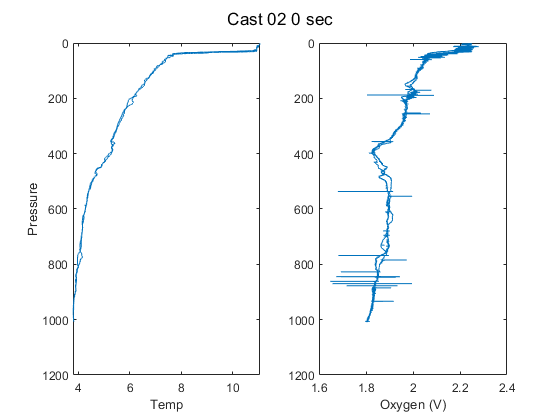

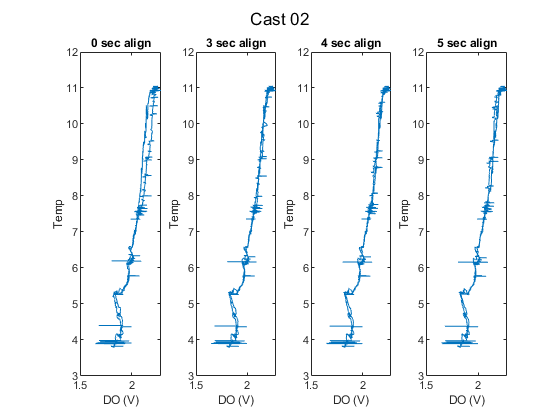

% cast = alignCTD_KF(cast,CastString,a1,a2,a3) % Function
a1 = 3; a2 = 4; a3 = 5;

% cast01 = align_CTD_KF(cast01,'Cast 01',a1,a2,a3);
cast02 = align_CTD_KF(cast02,'Cast 02',a1,a2,a3);

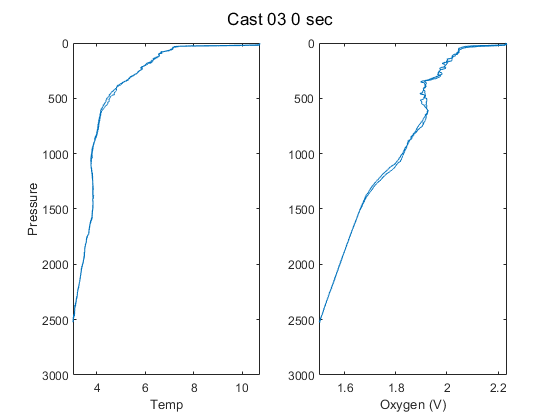

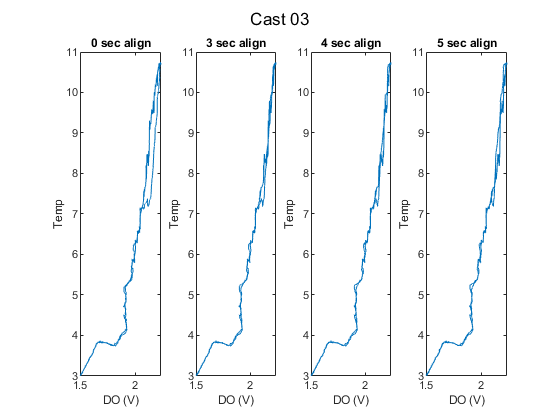

cast03 = align_CTD_KF(cast03,'Cast 03',a1,a2,a3);

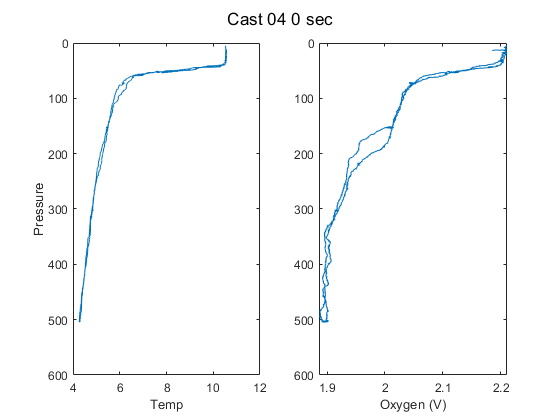

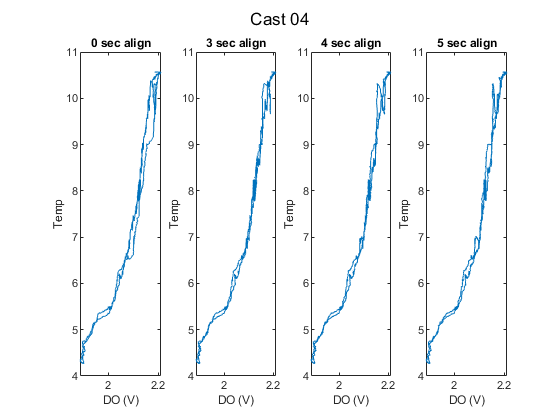

cast04 = align_CTD_KF(cast04,'Cast 04',a1,a2,a3);

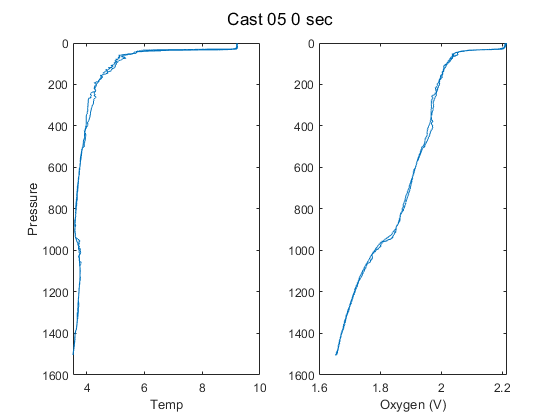

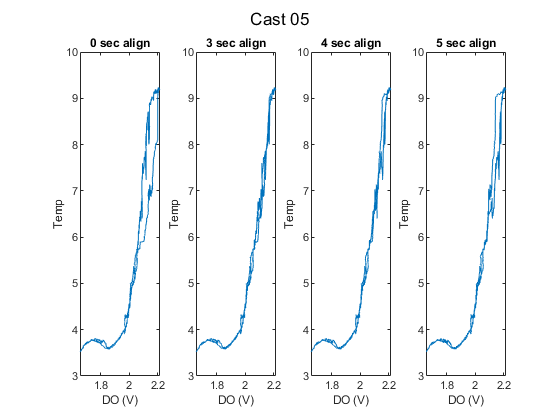

cast05 = align_CTD_KF(cast05,'Cast 05',a1,a2,a3);

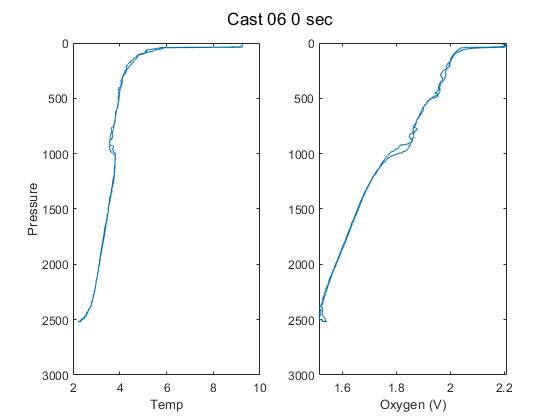

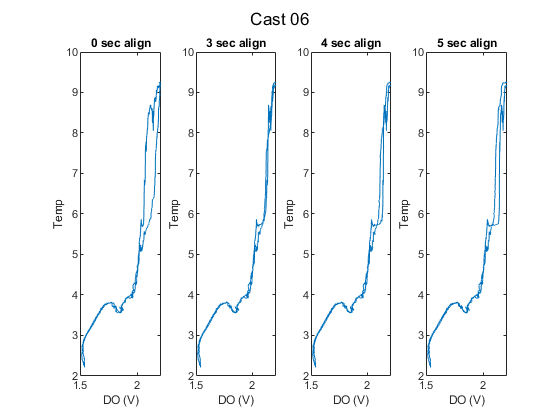

cast06 = align_CTD_KF(cast06,'Cast 06',a1,a2,a3);

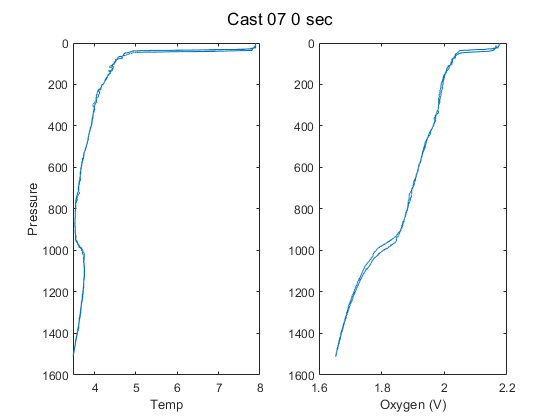

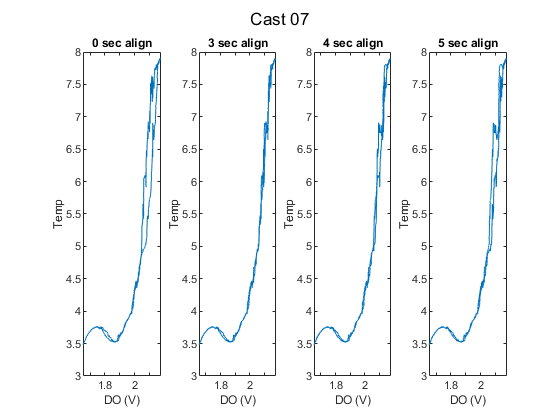

cast07 = align_CTD_KF(cast07,'Cast 07',a1,a2,a3);

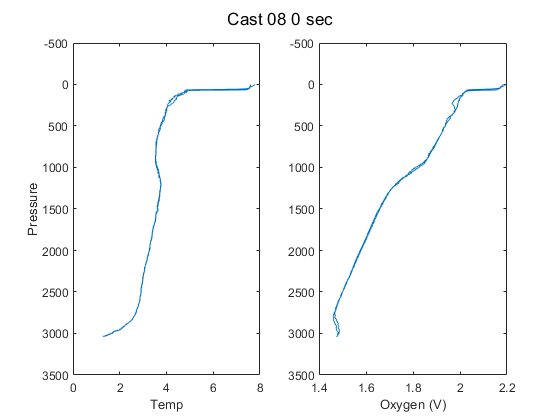

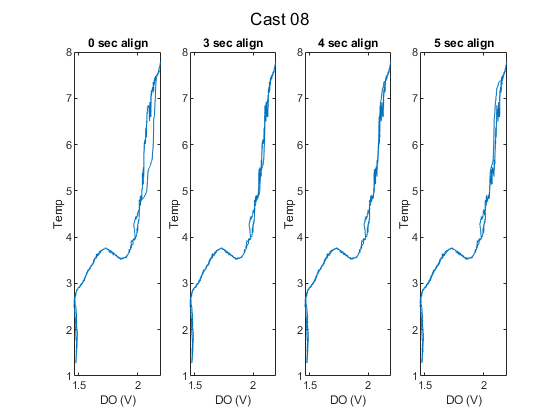

cast08 = align_CTD_KF(cast08,'Cast 08',a1,a2,a3);

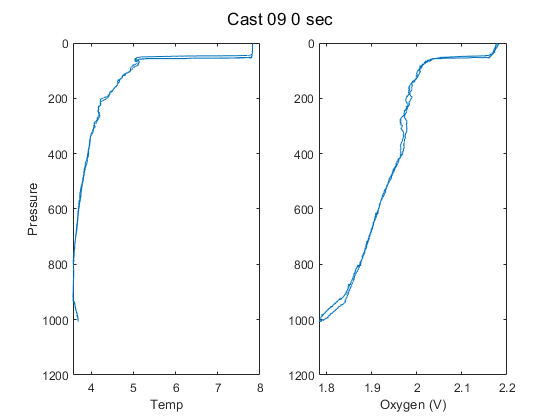

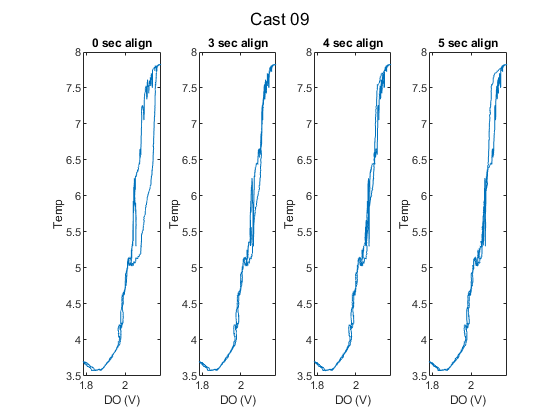

cast09 = align_CTD_KF(cast09,'Cast 09',a1,a2,a3);


% Pick align_sec

align_sec = a2; 

% cast01.DOv = SBE_alignCTDW(cast01.sbeox0V, align_sec, 1/24 );
cast02.DOv = SBE_alignCTDW(cast02.sbeox0V, align_sec, 1/24 );
cast03.DOv = SBE_alignCTDW(cast03.sbeox0V, align_sec, 1/24 );
cast04.DOv = SBE_alignCTDW(cast04.sbeox0V, align_sec, 1/24 );
cast05.DOv = SBE_alignCTDW(cast05.sbeox0V, align_sec, 1/24 );
cast06.DOv = SBE_alignCTDW(cast06.sbeox0V, align_sec, 1/24 );
cast07.DOv = SBE_alignCTDW(cast07.sbeox0V, align_sec, 1/24 );
cast08.DOv = SBE_alignCTDW(cast08.sbeox0V, align_sec, 1/24 );
cast09.DOv = SBE_alignCTDW(cast09.sbeox0V, align_sec, 1/24 );

% H = [-0.02, 5000, 1850];
% align = 1; 
% [cast03] = adjust_hysteresis_KF(cast03,'Cast 03',H,cal,align);
% [cast04] = adjust_hysteresis_KF(cast04,'Cast 04',H,cal,align);
% [cast05] = adjust_hysteresis_KF(cast05,'Cast 05',H,cal,align);

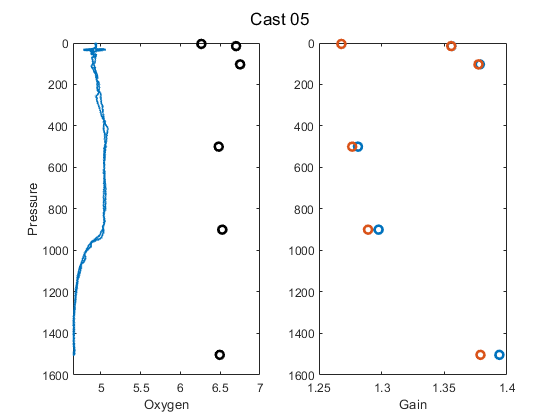

Gain = 1.3291+/- 0.053612
EGain = 1.3242+/- 0.051892


E = cal.E;
E2 = 3.8e-2;

btlsum05 = CTD_Gain_KF(btlsum05,cast05,'Cast 05',E,E2);

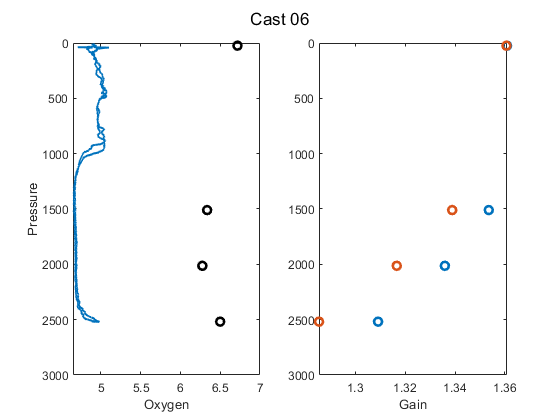

Gain = 1.3399+/- 0.023035
EGain = 1.3254+/- 0.032166


btlsum06 = CTD_Gain_KF(btlsum06,cast06,'Cast 06',E,E2);

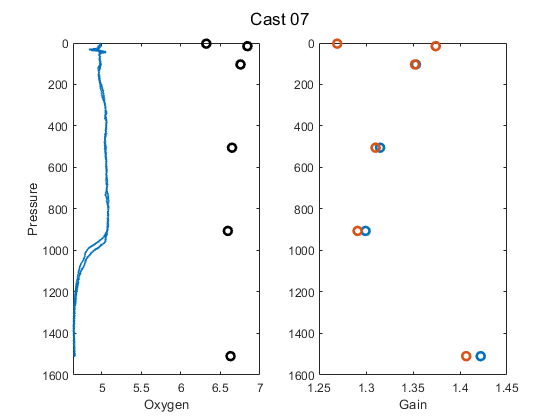

Gain = 1.3389+/- 0.055346
EGain = 1.3339+/- 0.052527


btlsum07 = CTD_Gain_KF(btlsum07,cast07,'Cast 07',E,E2);

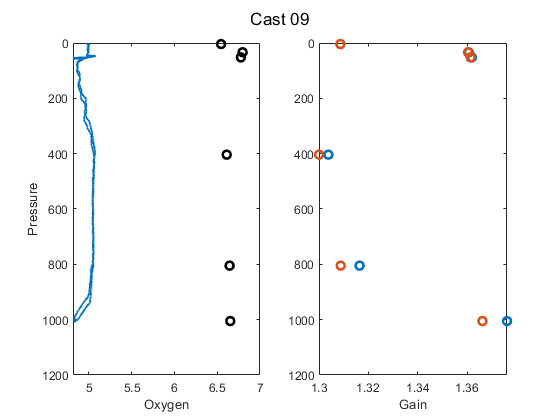

Gain = 1.338+/- 0.03178
EGain = 1.3342+/- 0.031398


btlsum09 = CTD_Gain_KF(btlsum09,cast09,'Cast 09',E,E2);

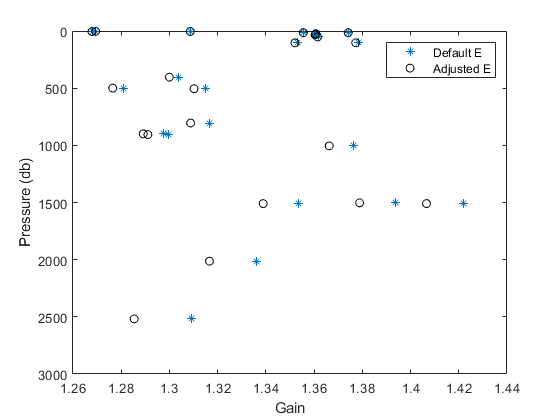

btlsum = [btlsum05; btlsum06; btlsum07; btlsum09];

depth_cut = 500;

figure
plot(btlsum.gain,btlsum.PrDM,'*')
hold on
plot(btlsum.Egain,btlsum.PrDM,'ok')
% plot(btlsum.Egain(btlsum.PrDM > depth_cut),btlsum.PrDM(btlsum.PrDM > depth_cut),'ok')
axis ij
ylabel('Pressure (db)')
xlabel('Gain')
legend('Default E','Adjusted E','Location','NE')


disp(['Gain = ' num2str(nanmean(btlsum.gain(btlsum.PrDM > depth_cut))) '+/- ' num2str(nanstd(btlsum.gain(btlsum.PrDM > depth_cut)))])

Gain = 1.3419+/- 0.043063


disp(['EGain = ' num2str(nanmean(btlsum.Egain(btlsum.PrDM > depth_cut))) '+/- ' num2str(nanstd(btlsum.Egain(btlsum.PrDM > depth_cut)))])

EGain = 1.3292+/- 0.041956


cal.SOCnew = cal.SOC*nanmean(btlsum.Egain(btlsum.PrDM > depth_cut));
disp(['DO align (s) = ' num2str(align_sec)])

DO align (s) = 4


disp(['Cal. E term = ' num2str(cal.E)])

Cal. E term = 0.036


disp(['Adjust. E term = ' num2str(E2)])

Adjust. E term = 0.038


disp(['Cal SOC = ' num2str(cal.SOC)])

Cal SOC = 0.45593


disp(['New SOC = ' num2str(cal.SOCnew) ])

New SOC = 0.60601
